# ARMA Residual Diagnostics

Remember the starting point of our analysis. We do time series modelling if the data shows us some interesting form of serial dependence. If we have serially correlated data, then the past can help us make a better prediction of the future. The goal of the modelling exercise is to obtain error terms that are uncorrelated from each other (i.e. are not serially correlated).

We will study the error terms from the preferred model of the last class as well as of the random walk model. We will study the autocorrelation of the residuals using three different techniques:

- We can compute the sample autocorrelation and sample partial autocorrelation;

- We can compute the Q statistic (Ljung Box Test);

- We can do the LM test for serial correlation.

Rather than simply loading the `term_premium` dataset, let's use the `fetch` function to see one more time how to use this function to import data. Remember that we need the 1-year and 10-year treasury rates to build the term premium series.

% Downloading the 1-year rate data: 
gs1 = fetch(fred(), 'GS1')

gs1 = struct with fields:
                 Title: ' 1-Year Treasury Constant Maturity Rate'
              SeriesID: ' GS1'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1953-04-01 to 2019-12-01'
           LastUpdated: ' 2020-01-02 8:18 PM CST'
                 Notes: ' Averages of business days. For further information regarding treasury constant maturity data, please refer to http://www.federalreserve.gov/releases/h15/current/h15.pdf and http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx.'
                  Data: [801×2 double]


% Downloading the 10-year rate data:
gs10 = fetch(fred(), 'GS10')

gs10 = struct with fields:
                 Title: ' 10-Year Treasury Constant Maturity Rate'
              SeriesID: ' GS10'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1953-04-01 to 2019-12-01'
           LastUpdated: ' 2020-01-02 8:18 PM CST'
                 Notes: ' Averages of business days. For further information regarding treasury constant maturity data, please refer to the Board of Governors (http://www.federalreserve.gov/releases/h15/current/h15.pdf) and the Treasury (http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx).'
                  Data: [801×2 double]


At this stage, it might be a good idea to remember what a structure is. A structure is a type of data that pretty much lets you store whatever you like into it. But the way you store the information and access it is different from a cell. The way to access the structure is similar to a class in C or Java. You can write the name of a structure, followed by the name of the item, in order to save or access information that is saved under this identifier. Here is an illustration:

% Getting the information in the "Title" section of the structure:
gs10.Title

ans = ' 10-Year Treasury Constant Maturity Rate'

% Getting the information in the "Notes" section of the structure:
gs10.Notes

ans = ' Averages of business days. For further information regarding treasury constant maturity data, please refer to the Board of Governors (http://www.federalreserve.gov/releases/h15/current/h15.pdf) and the Treasury (http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx).'

We can also add properties to a structure as we wish:

gs10.Course = 'MSc in Financial Economics'

gs10 = struct with fields:
                 Title: ' 10-Year Treasury Constant Maturity Rate'
              SeriesID: ' GS10'
                Source: ' Board of Governors of the Federal Reserve System (US)'
               Release: ' H.15 Selected Interest Rates'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1953-04-01 to 2019-12-01'
           LastUpdated: ' 2020-01-02 8:18 PM CST'
                 Notes: ' Averages of business days. For further information regarding treasury constant maturity data, please refer to the Board of Governors (http://www.federalreserve.gov/releases/h15/current/h15.pdf) and the Treasury (http://www.treasury.gov/resource-center/data-chart-center/interest-rates/Pages/yieldmethod.aspx).'
                  Data: [801×2 double]
                Course: 'MSc in Financial Economics'


Let's build the series of the term premium one more time and plot it:

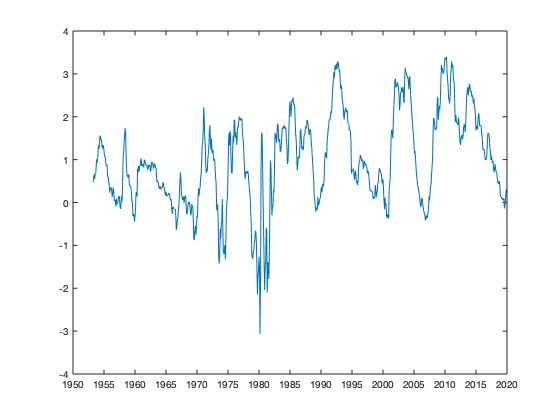

% Building the term premium series:
tp = gs10.Data(:,2) - gs1.Data(:,2);
% Let's also build a series of dates (simplifies plotting):
dates = gs10.Data(:,1);
% Finally plotting:
plot(dates,tp)
datetick('x')

## Excercise 59 

Ok! After some intro and review of the series we are working with, let's get into the problem. This exercise asks us to analyse the residuals from our preferred model from Exercise 58 as well as a random-walk model.

In Exercise 58, the different model selection techniques yielded:

- AIC: ARMA(2,1)

- BIC: ARMA(1,1)

- StG: ARMA(1,1)

- GtS: ARMA(4,4)

In order to keep the model as parsimonious as possible, let's proceed with the ARMA(1,1). 

### Exercise 59 a. Plot the residuals

The first part of the exercise is to plot the residuals of both our selected ARMA(1,1) model and a random-walk. In order to do this, we first need to estimate the ARMA(1,1) model using Kevin's `armaxfilter`. Recall that we can get the series of residuals from the model as the third output from the `armaxfilter `function (see **help** `armaxfilter`).

% Setting the optimization display options:
options.Display='none';
% Estimating the model:
[p,ll,err] = armaxfilter(tp,1,1,1,[],[],options);

Now that we have the series of the residuals, we can plot them. In order to have more interpretable residuals, we can normalize them simply by dividing the series of residuals by its standard deviation (since they are mean zero by construction).

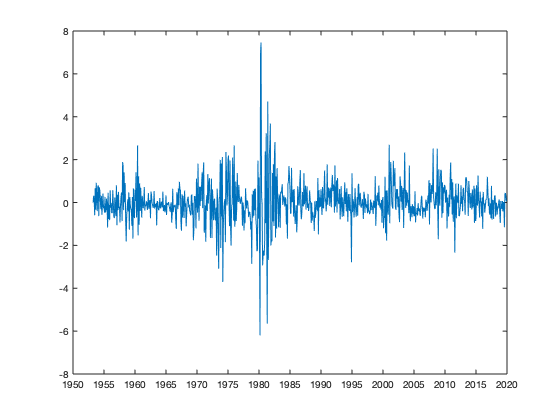

% Standardizing the residuals:
stderrors = err / std(err);
% Plotting the residuals:
plot(dates,stderrors)
datetick('x')

Do these errors seem to have serial correlation? This is hard to say without further analysis. Note that the error terms are obviously heteroskedastic. In the beginning of the 1980s, at a time of high inflation, we observed the largest error terms. 

It might help to compare these errors with those of a random-walk model. Remember that a random-walk model is defined as:


$$y_t =y_{t-1} +\varepsilon_t \;$$


Therefore, the residuals of a random-walk model can be written as:


$$\varepsilon_t =y_t -y_{t-1}$$


With this in mind, we can construct the series of residuals of a random-walk model for the term premium as:

err = diff(tp);
stderrors_rw = err/std(err);

Now let's plot these against the standardized residuals of our selected model to compare:

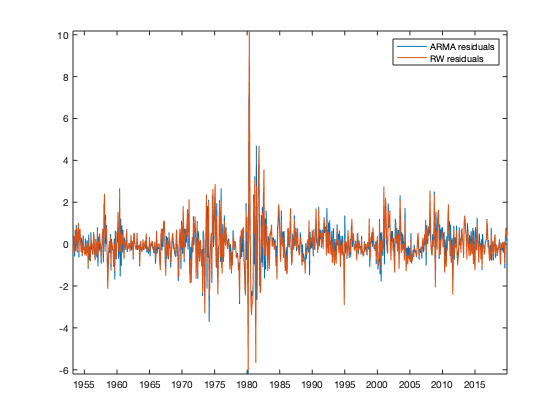

% Here we can see the benefit of using "hold" (plotting series of different sizes):
figure()
plot(dates, stderrors)
hold on
plot(dates(2:end), stderrors_rw)
hold off
legend('ARMA residuals', 'RW residuals')
datetick('x')
axis tight

The residuals from the random-walk model appear to have much more dynamics in them than the ones from the ARMA(1,1) model. Nevertheless, it is still hard to say if the residuals from the ARMA(1,1) model present serial correlation or not. A better way to analyse this will be to check the autocorrelogram and partial autocorrelogram.

### Exercise 59 b. Autocorrelograms

Let's first take a look at the autocorrelogram. Again, Kevin's MFE toolbox will come in handy. It allows us to plot sample autocorrelations in an autocorrelogram with the simple command `sacf`:

help sacf

  Computes sample autocorrelations and standard deviation using either heteroskedasticity robust
  standard errors or classic (homoskedastic) standard errors 
 
  USAGE:
   [AC,ACSTD] = sacf(DATA,LAGS)
   [AC,ACSTD,HFIG] = sacf(DATA,LAGS,ROBUST,GRAPH)
 
  INPUTS:
   DATA   - A T by 1 vector of data
   LAGS   - The number of autocorrelations to compute
   ROBUST - [OPTIONAL] Logical variable (0 (non-robust) or 1 (robust)) to indicate whether
              heteroskedasticity robust standard errors should be used. Default is to use robust
              standard errors (ROBUST=1).   
   GRAPH  - [OPTIONAL] Logical variable (0 (no graph) or 1 (graph)) indicating whether the function
              should produce a bar plot of the sample autocorrelations and confidence intervals.
              Default is to produce a graphic (GRAPH=1).  
 
  OUTPUTS:
   AC     - A LAGS by 1 vector of autocorrelations
   ACSTD  - A LAGS by 1 vector of standard deviations
   HFIG   - Figure handle to the bar pl

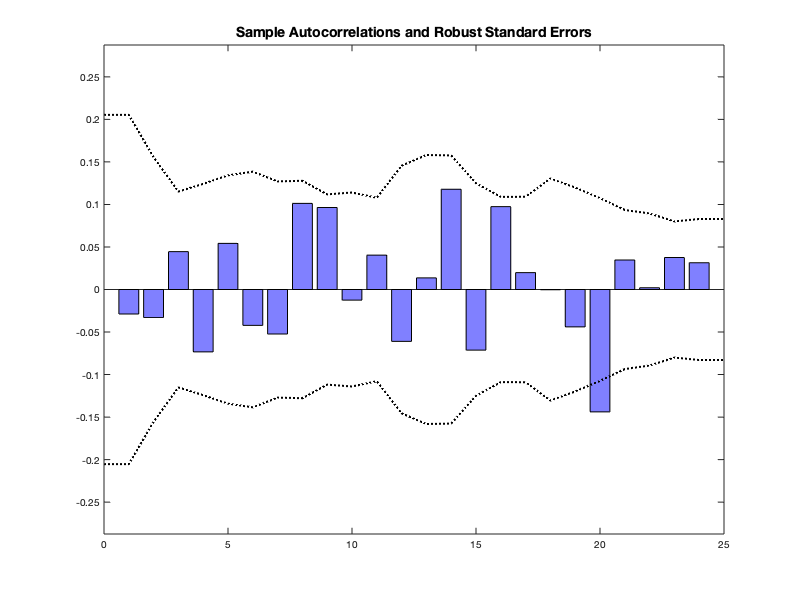

sacf(stderrors, 24);

Just to be sure, let's also check the partial autocorrelogram. Sample partial autocorrelations can also be calculated and plotted using Kevin's MFE toolbox. In order to do so, we use the function `spacf` . 

help spacf

  Computes sample partial autocorrelations and standard deviation using either heteroskedasticity
  robust standard errors or classic (homoskedastic) standard errors
 
  USAGE:
   [PAC,PACSTD] = spacf(DATA,LAGS)
   [PAC,PACSTD,HFIG] = spacf(DATA,LAGS,ROBUST)
 
  INPUTS:
   DATA      - A T by 1 vector of data
   LAGS      - The number of autocorrelations to compute
   ROBUST    - [OPTIONAL] Logical variable (0 (non-robust) or 1 (robust)) to indicate whether
                 heteroskedasticity robust standard errors should be used. Default is to use robust
                 standard errors (ROBUST=1).
   GRAPH     - [OPTIONAL] Logical variable (0 (no graph) or 1 (graph)) indicating whether the
                 function should produce a bar plot of the sample autocorrelations and confidence
                 intervals. Default is to produce a graphic (GRAPH=1).
 
  OUTPUTS:
   PAC        - A LAGS by 1 vector of partial autocorrelations
   PACSTD     - A LAGS by 1 vector of standard deviatio

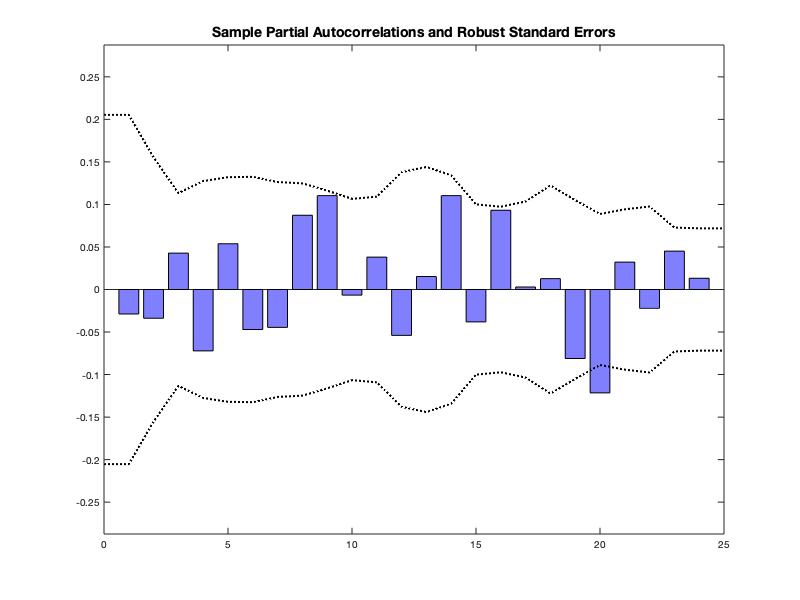

spacf(stderrors, 24);

The outcome of these plots is good, because we fail to reject our ARMA (1,1) model from the perspective of residual serial correlation. We can take a look into the ACFs and PACFs for the random-walk model to see the differences in comparison to our ARMA(1,1) model.

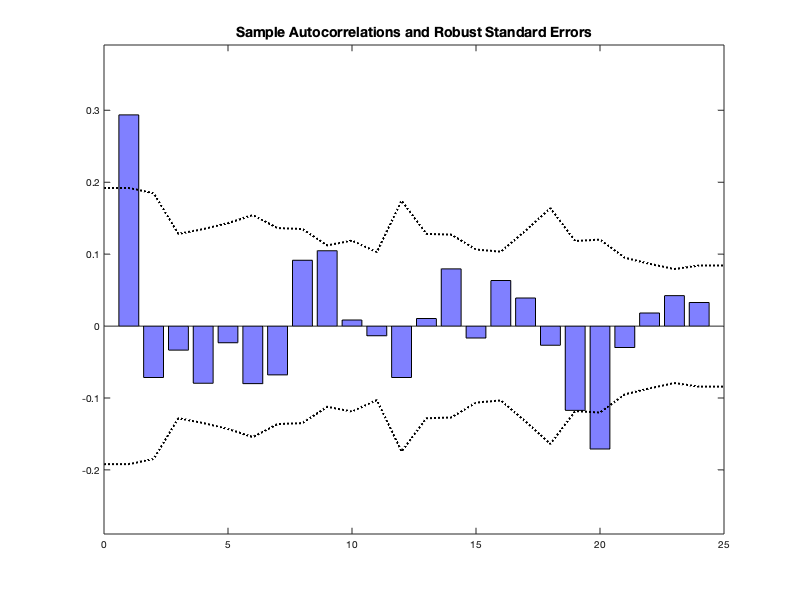

sacf(stderrors_rw, 24);

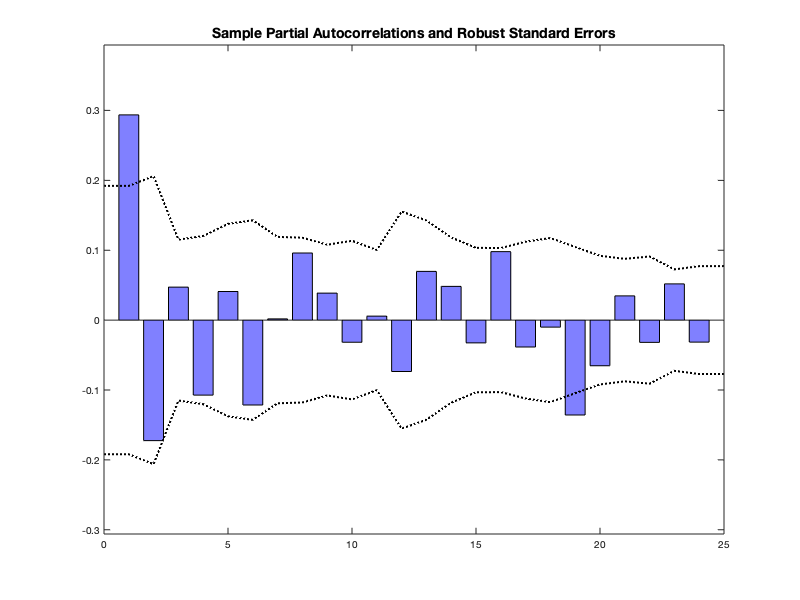

spacf(stderrors_rw, 24);

According to the sample autocorrelations and partial autocorrelations, there is no serial dependence in the error terms of our ARMA(1,1). The graphs for the random-walk model further contribute to our understanding that the most important dynamics to be modelled are those with respect to the first lag. 

Note though that the sample autocorrelation and partial autocorrelation functions are all individual tests of serial correlation at a specific lag length. What we are really interested in is the null hypothesis that the serial correlation at all lag length is zero. This is like a joint hypothesis. 

We have two ways of implementing a statistical test with this type of joint null hypothesis. We can use the Ljung Box test or the LM test. The Ljung Box test relies on the assumption of homoskedasticity. Therefore, it would be better to use the LM test, which is robust to heteroskedasticity. For both tests, we are trying to reject the joint null hypothesis of no serial correlation up to a specific lag length.

### Exercise 59 c. Ljung Box Test 

From Pg 241 of Kevin's notes we have:

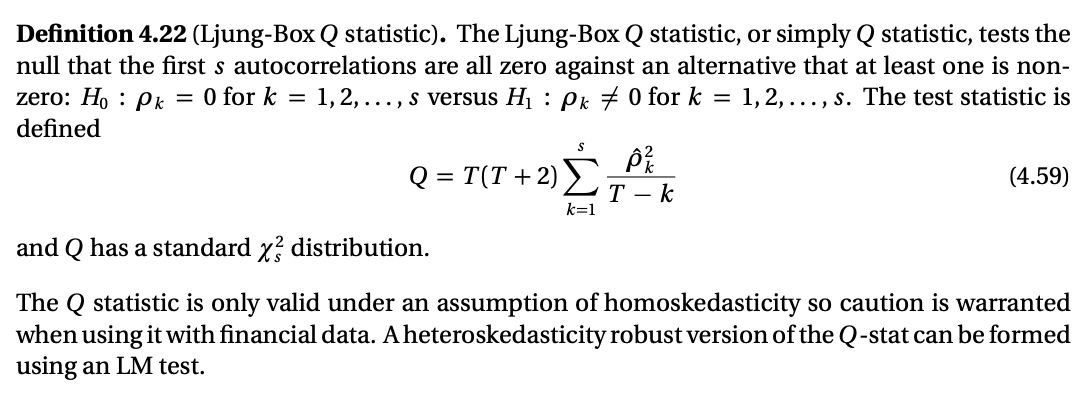

The MFE Toolbox is equipped with the `ljungbox` function, that allows us to calculate the Q statistic for a given lag number and hence compute the Ljung Box Test:

help ljungbox

  Ljung-Box tests for the presence of serial correlation in up to q lags.  Returns LAGS Ljung-Box
  statistics tests, one for tests for each lag between 1 and LAGS. Under the null of no serial
  correlation and assuming homoskedasticity, the Ljung-Box test statistic is asymptotically
  distributed X2(q)   
  
  USAGE:
   [Q,PVAL] = ljungbox(DATA,LAGS)
  
  INPUTS:
   DATA      - A T by 1 vector of data
   LAGS      - The maximum number of lags to compute the LB.  The statistic and pval will be
                 returned for all sets of lags up to and including LAGS 
  
  OUTPUTS:
   Q         - A LAGS by 1 vector of Q statistics
   PVAL      - A LAGS by 1 set of appropriate pvals
  
  COMMENTS:
   This test statistic is common but often inappropriate since it assumes homoskedasticity.  For a
   heteroskedasticity consistent serial correlation test, see lmtest1 
 
  SEE ALSO:
   lmtest1, sacf, sp

[~, pv] = ljungbox(stderrors,12)

pv =       0.41402
      0.46222
      0.36959
      0.11221
     0.078978
     0.079305
     0.060222
    0.0052333
   0.00055967
    0.0010326


Since the null in the Ljung Box Test is that there is no serial correlation in the residuals up to the lag being tested, the p-values above contribute to the hypothesis that is no serial correlation in the residuals of our ARMA(1,1) model.

For comparison, let's see how the results of this test for the residuals of the random-walk model look like:

[~, pv] = ljungbox(stderrors_rw,12)

pv =    1.1102e-16
   1.1102e-16
   5.5511e-16
   2.2204e-16
   8.8818e-16
   3.3307e-16
   2.2204e-16
            0
            0
            0


As we can see above, there is strong evidence of serial correlation in the residuals of the random-walk model. 

This is all very interesting. But because the Ljung Box Test assumes homoskedasticity, it is not very useful when dealing with financial data. Now let's proceed to the heteroskedasticy robust LM Test.

### Exercise 59 d. LM Test for Serial Correlation 

From Pg 241 of Kevin's notes we have:

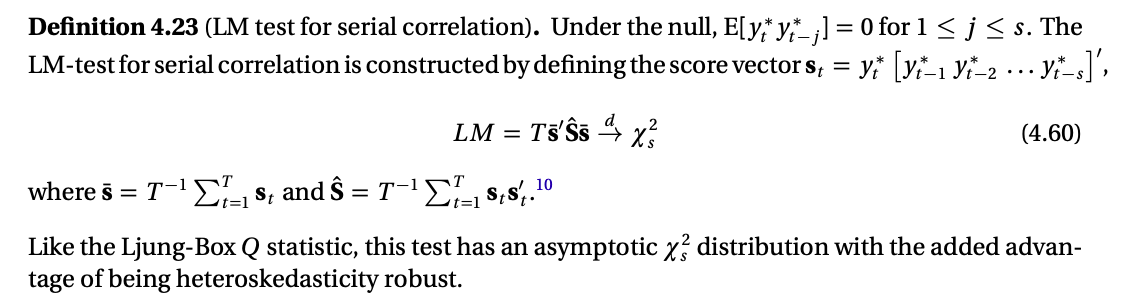

One more time, our life is made a lot easier because of Kevin's MFE Toolbox. This Toolbox is equipped with the `lmtest1` function that allows us to calculate the LM test statistic for a given lag number and hence compute the LM Test for serial correlation:

help lmtest1

  LM tests for the presence of serial correlation in q lags, with or without heteroskedasticity.
  Returns Q LM tests, one for tests for each lag between 1 and Q. Under the null of no serial
  correlation, the LM-test is asymptotically  distributed X2(q)  
  
  USAGE:
   [LM,PVAL] = lmtest1(DATA,Q)
   [LM,PVAL] = lmtest1(DATA,Q,ROBUST)
  
  INPUTS:
   DATA      - A T by 1 vector of data
   Q         - The maximum number of lags to regress on.  The statistic and pval will be returned
                 for all sets of lags up to and including q 
   ROBUST    - [OPTIONAL] Logical variable (0 (non-robust) or 1 (robust)) to  indicate whether
                 heteroskedasticity robust standard errors  should be used. Default is to use robust
                 standard errors (ROBUST=1).  
  
  OUTPUTS:
   LM        - A Qx1 vector of statistics
   PVAL      - A Qx1 set of appropriate pvals
  
  
  COMMENTS:
  The variance estimator is computed under the alterna

[~, pv] = lmtest1(stderrors,12)

pv =       0.77873
       0.8139
      0.82142
      0.69533
      0.79322
      0.79436
      0.84913
      0.66386
      0.46165
      0.55586


We can see that by using a heteroskedasticity robust version of a test for serial correlation, we have an even stronger evidence that the residuals of our ARMA(1,1) do not present serial correlation.

Let's conduce the LM test for serial correlation using the residuals of the random-walk model for comparison:

[~, pv] = lmtest1(stderrors_rw,12)

pv =     0.0020583
    0.0081402
     0.016867
    0.0083406
     0.015708
     0.006093
     0.011733
     0.010457
    0.0096213
     0.011374


Again, there is strong evidence of serial correlation in the residuals of the random-walk model. This is because the random walk model does not fully capture the temporal dependence of the data. Overall, the results from this section makes us feel very confident that our ARMA(1,1) does a good job in capturing this temporal dependence observed in the data. 

Before we finish this section, let's just save the `tp` and `dates` data so that we don't have recalculate everything in the next exercises.

save term_premium tp dates